%%y方向7101
%7100
[~,ia] = unique(y_axis_7100(:,1));
[~,ia2] = unique(y_hoop_7100(:,1));
YY = linspace(min(y_axis_7100(ia,1)),max(y_axis_7100(ia,1)),100)';
Y_axis_s_7100 = interp1(y_axis_7100(ia,1),y_axis_7100(ia,2),YY,'spline');
Y_hoop_s_7100 = interp1(y_hoop_7100(ia2,1),y_hoop_7100(ia2,2),YY,'spline');
%7104
[~,ia] = unique(y_axis_7104(:,1));
[~,ia2] = unique(y_hoop_7104(:,1));
% YY_7104 = linspace(min(y_axis_7104(ia,1)),max(y_axis_7104(ia,1)),100)';
Y_axis_s_7104 = interp1(y_axis_7104(ia,1),y_axis_7104(ia,2),YY,'spline');
Y_hoop_s_7104 = interp1(y_hoop_7104(ia2,1),y_hoop_7104(ia2,2),YY,'spline');
%%x方向
%7100
[~,ia] = unique(x_axis_7100(:,1));
[~,ia2] = unique(x_hoop_7100(:,1));
XX = linspace(min(x_axis_7100(ia,1)),max(x_axis_7100(ia,1)),100)';
X_axis_s_7100 = interp1(x_axis_7100(ia,1),x_axis_7100(ia,2),XX,'spline');
X_hoop_s_7100 = interp1(x_hoop_7100(ia2,1),x_hoop_7100(ia2,2),XX,'spline');
%7104
[~,ia] = unique(x_axis_7104(:,1));
[~,ia2] = unique(x_hoop_7104(:,1));
% XX_7104 = linspace(min(x_axis_7104(ia,1)),max(x_axis_7104(ia,1)),100)';
X_axis_s_7104 = interp1(x_axis_7104(ia,1),x_axis_7104(ia,2),XX,'spline');
X_hoop_s_7104 = interp1(x_hoop_7104(ia2,1),x_hoop_7104(ia2,2),XX,'spline');

## HUITU

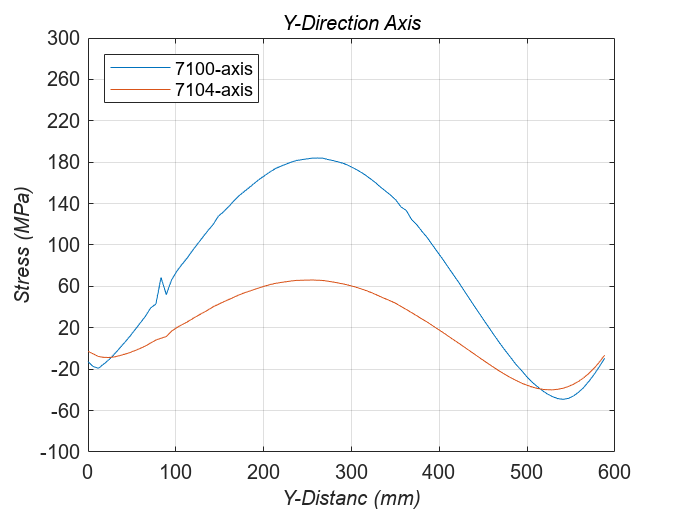

%%Y方向
%Y-axis
figure(1)
h = plot([YY,YY],[Y_axis_s_7100,Y_axis_s_7104],'MarkerFaceColor','auto');
set(h, {'MarkerFaceColor'}, get(h,'Color'));
grid on
xlabel('Y-Distanc (mm)','fontsize',10,"FontAngle","italic");
ylabel('Stress (MPa)','fontsize',10,"FontAngle","italic");
legend('7100-axis','7104-axis','Orientation','vertical')
set(legend,'Location','NorthWest');
ylim([-100,300]);
yticks(-100:40:300);
title('Y-Direction Axis','fontsize',10,"FontAngle","italic")

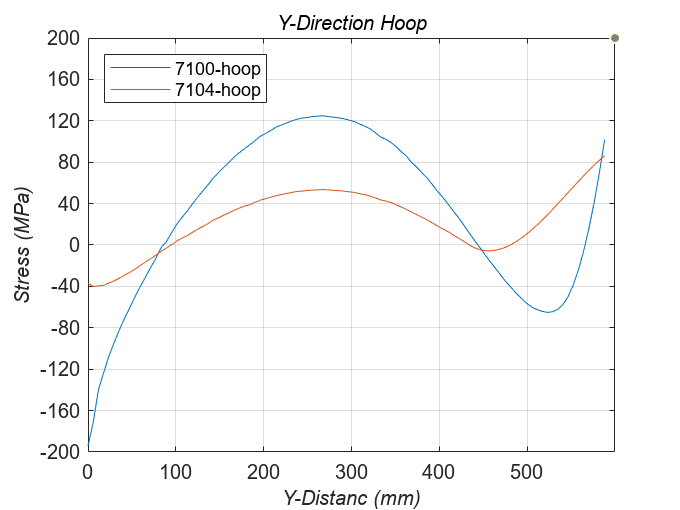


%Y-hoop
figure(2)
h = plot([YY,YY],[Y_hoop_s_7100,Y_hoop_s_7104],'MarkerFaceColor','auto');
set(h, {'MarkerFaceColor'}, get(h,'Color'));
grid on
xlabel('Y-Distanc (mm)','fontsize',10,"FontAngle","italic");
ylabel('Stress (MPa)','fontsize',10,"FontAngle","italic");
legend('7100-hoop','7104-hoop','Orientation','vertical')
set(legend,'Location','NorthWest');
ylim([-200,200]);
yticks(-200:40:200);
title('Y-Direction Hoop','fontsize',10,"FontAngle","italic")

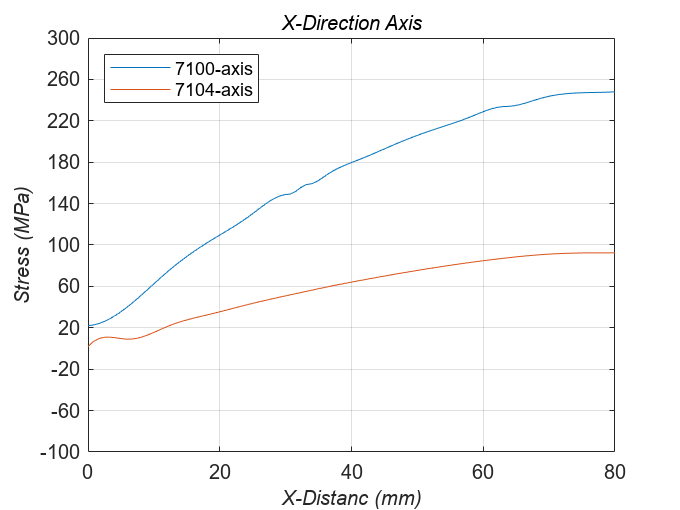


%%X方向
%X-axis
figure(3)
h = plot([XX,XX],[X_axis_s_7100,X_axis_s_7104],'MarkerFaceColor','auto');
set(h, {'MarkerFaceColor'}, get(h,'Color'));
grid on
xlabel('X-Distanc (mm)','fontsize',10,"FontAngle","italic");
ylabel('Stress (MPa)','fontsize',10,"FontAngle","italic");
legend('7100-axis','7104-axis','Orientation','vertical')
set(legend,'Location','NorthWest');
ylim([-100,300]);
yticks(-100:40:300);
title('X-Direction Axis','fontsize',10,"FontAngle","italic")

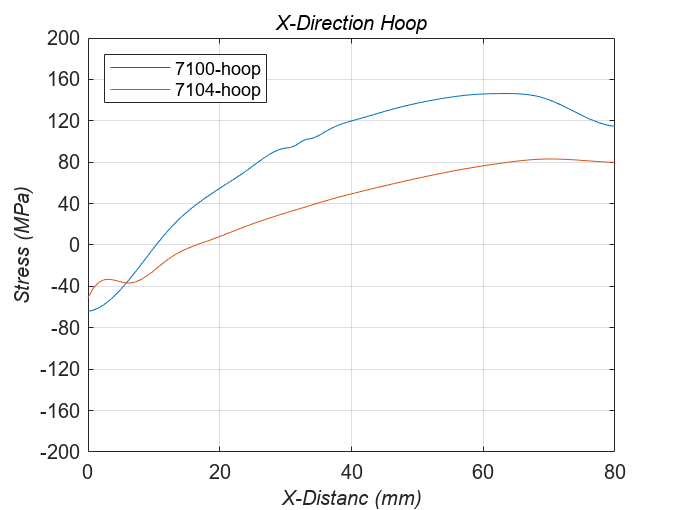


%X-hoop
figure(4)
h = plot([XX,XX],[X_hoop_s_7100,X_hoop_s_7104],'MarkerFaceColor','auto');
set(h, {'MarkerFaceColor'}, get(h,'Color'));
grid on
xlabel('X-Distanc (mm)','fontsize',10,"FontAngle","italic");
ylabel('Stress (MPa)','fontsize',10,"FontAngle","italic");
legend('7100-hoop','7104-hoop','Orientation','vertical')
set(legend,'Location','NorthWest');
ylim([-200,200]);
yticks(-200:40:200);
title('X-Direction Hoop','fontsize',10,"FontAngle","italic")